# Convolutional Coding For Rate = 1/3 and Kc = 6


EbNodB = 0:0.5:10;
R = 1/3;
k =1;
n =3;
kc = 6;

% Generating Practical_error and Theoratical_error matrices
practical_error_Hard = zeros(1,length(EbNodB));
practical_error_Soft = zeros(1, length(EbNodB));
theoratical_error = zeros(1,length(EbNodB));

idx =1;
idx2=1;
N = 2000;

for j=EbNodB
     EbNo = 10^(j/10);
     sigma = sqrt (1/(2 * R * EbNo));
     BER_th = 0.5*erfc(sqrt(EbNo));
     No_of_errors_hard = 0;
     No_of_errors_soft = 0;
     len = 0;
    for i = 1 : N
        % Generate random message
        msg = randi ([0 1],1,10); 
        msg=[msg zeros(1,kc-1)];

        encoded_array=Encoder(msg);  % Encoding the msg

        modulated_message= Modulation(encoded_array,sigma);  % Modulating the msg through BPSK

        demodualted_message=modulated_message<0;  % Demodulating the msg

        % Call Viterbi function
        decoded_message_hard= Hard_Decoder(demodualted_message);
        decoded_msg_soft = Soft_Decoder(modulated_message);

        No_of_errors_hard = No_of_errors_hard + sum(msg ~= decoded_message_hard);
        No_of_errors_soft = No_of_errors_soft + sum(msg ~= decoded_msg_soft);
    end 

     practical_error_Hard(idx) = (No_of_errors_hard/(N*length(msg)));
     practical_error_Soft(idx) = (No_of_errors_soft / (N*length(msg)));
     theoratical_error(idx2) = BER_th;
     idx = idx+1;
     idx2 = idx2+1;
 
end

practical_error_Soft

practical_error_Soft =     0.2472    0.2017    0.1485    0.1104    0.0829    0.0459    0.0254    0.0148    0.0067    0.0038    0.0019    0.0010    0.0006    0.0002    0.0001    0.0000    0.0000         0         0         0         0


practical_error_Hard

practical_error_Hard =     0.2992    0.2686    0.2211    0.1976    0.1537    0.1247    0.0776    0.0551    0.0338    0.0186    0.0113    0.0046    0.0021    0.0014    0.0007    0.0003    0.0000    0.0000         0    0.0000         0


theoratical_error

theoratical_error =     0.0786    0.0671    0.0563    0.0464    0.0375    0.0297    0.0229    0.0172    0.0125    0.0088    0.0060    0.0039    0.0024    0.0014    0.0008    0.0004    0.0002    0.0001    0.0000    0.0000    0.0000


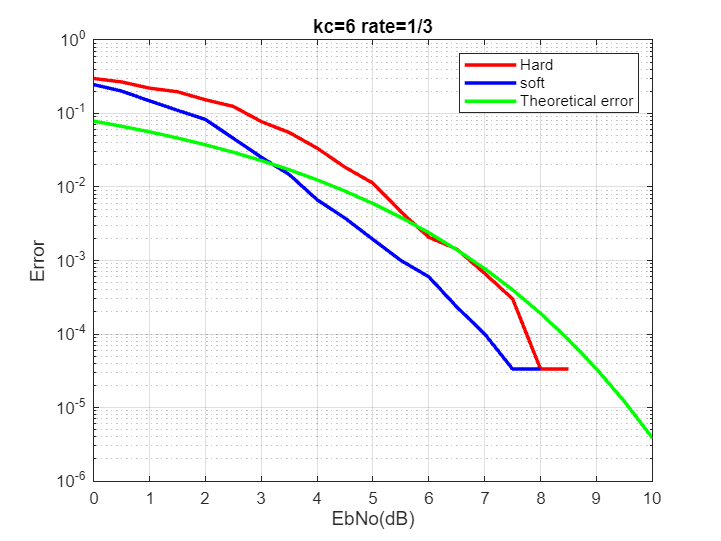

semilogy(EbNodB, practical_error_Hard, 'r-', 'LineWidth', 2.0);
hold on;
semilogy(EbNodB, practical_error_Soft, 'b-', 'LineWidth', 2.0);
semilogy(EbNodB, theoratical_error, 'g-', 'LineWidth', 2.0);
legend('Hard','soft', 'Theoretical error');
title('kc=6 rate=1/3');
grid on;

xlabel('EbNo(dB)');
ylabel('Error');
hold off;

## Encoder Function



function obs = Encoder(inputs)
    
    g1 = [1 0 0 1 1 1]; % Generator polynomial for output bit 1
    g2 = [1 0 1 0 1 1]; % Generator polynomial for output bit 2
    g3 = [1 1 1 1 0 1]; % Generator polynomial for output bit 3

    obs = zeros(1, length(inputs) * 3);
    state = [0 0 0 0 0];
    obs_idx = 1;

    % Iterate over input sequence
    for i = 1:length(inputs)

        % Update the state of the encoder

        register = [inputs(i) state];
        state = [inputs(i) state(1:4)];

        % Encode the input message using the generator polynomials

        out1 = mod(register*g1', 2);
        out2 = mod(register*g2', 2);
        out3 = mod(register*g3', 2);

        % Store encoded bits in 1D array

        obs(obs_idx) = out1;
        obs(obs_idx + 1) = out2;
        obs(obs_idx + 2) = out3;
        obs_idx = obs_idx + 3;
    end
    
end



## Modulation Function



function modulated_op = Modulation(encoded_message,sigma)
     s = 1 - 2 * encoded_message; % BPSK modulation
     modulated_op= s + sigma * randn(1, length(encoded_message));
end



## Hamming distance calculator


function dist = Hamming_Distance(x,y,w,z,p,q)
    dist = xor(x,z)+xor(y,p)+xor(w,q);
end



## Euclidean distance calculator Function


function dist = Euclidean_Distance(x,y,w,z,p,q)
    dist=sqrt((x-z)^2+(y-p)^2+(w-q)^2);
end


## Hard Decision Decoding Function


function A=Hard_Decoder(obs)

 % Trellis structure
start_metric = struct('zero', 0, 'one', 0, 'two', 0, 'three', 0 , 'four', 0 , 'five', 0 , 'six', 0 , 'seven', 0 ...
, 'eight', 0 , 'nine', 0 , 'ten', 0 , 'eleven', 0 , 'twelve', 0 , 'thirteen', 0 , 'fourteen', 0 , 'fifteen', 0 ...
, 'sixteen', 0 , 'seventeen', 0 , 'eighteen', 0 , 'ninteen', 0 , 'twenty', 0 , 'twentyone', 0 ,...
'twentytwo', 0 , 'twentythree', 0, 'twentyfour', 0 , 'twentyfive', 0 , 'twentysix', 0 ,...
 'twentyseven', 0 , 'twentyeight', 0 ,'twentynine', 0 , 'thirty', 0 , 'thirtyone', 0);

state_machine = struct( ...
'zero', ...
struct('b1', struct('out_b',[1 1 1], 'prev_st', 'one', 'input_b',0), ...
          'b2', struct('out_b', [0 0 0], 'prev_st', 'zero', 'input_b',0)), ...
'one', ...
struct('b1', struct('out_b', [0 0 1], 'prev_st', 'three', 'input_b',0), ...
          'b2', struct('out_b', [1 1 0], 'prev_st', 'two', 'input_b',0)), ...
'two', ...
struct('b1', struct('out_b', [1 0 1], 'prev_st', 'four', 'input_b',0), ...
          'b2', struct('out_b', [0 1 0], 'prev_st', 'five', 'input_b',0)), ... 
'three', ...
struct('b1', struct('out_b', [0 1 1], 'prev_st', 'six', 'input_b',0), ...
          'b2', struct('out_b', [1 0 0], 'prev_st', 'seven', 'input_b',0)), ... 
'four', ...
struct('b1', struct('out_b', [0 1 1], 'prev_st', 'eight', 'input_b',0), ...
          'b2', struct('out_b',[1 0 0], 'prev_st', 'nine', 'input_b',0)), ...
'five', ...
struct('b1', struct('out_b', [1 0 1], 'prev_st', 'ten','input_b', 0), ...
          'b2', struct('out_b', [0 1 0], 'prev_st', 'eleven', 'input_b',0)), ...
'six', ...
struct('b1', struct('out_b',[1 1 0], 'prev_st', 'twelve', 'input_b',0), ...
          'b2', struct('out_b', [0 0 1], 'prev_st', 'thirteen', 'input_b',0)), ...
'seven', ...
struct('b1', struct('out_b', [0 0 0], 'prev_st', 'fourteen','input_b', 0), ...
          'b2', struct('out_b', [1 1 1], 'prev_st', 'fifteen', 'input_b',0)), ...
'eight', ...
struct('b1', struct('out_b', [0 0 1], 'prev_st', 'sixteen', 'input_b',0), ...
          'b2', struct('out_b', [1 1 0], 'prev_st', 'seventeen', 'input_b',0)), ... 
'nine', ...
struct('b1', struct('out_b', [1 1 1], 'prev_st', 'eighteen', 'input_b',0), ...
          'b2', struct('out_b', [0 0 0], 'prev_st', 'ninteen', 'input_b',0)), ...
'ten', ...
struct('b1', struct('out_b', [1 0 0], 'prev_st', 'twenty', 'input_b',0), ...
          'b2', struct('out_b', [0 1 1], 'prev_st', 'twentyone', 'input_b',0)), ... 
'eleven', ...
struct('b1', struct('out_b', [0 1 0], 'prev_st', 'twentytwo', 'input_b',0), ...
          'b2', struct('out_b', [1 0 1], 'prev_st', 'twentythree', 'input_b',0)), ... 
'twelve', ...
struct('b1', struct('out_b', [0 1 0], 'prev_st', 'twentyfour', 'input_b',0), ...
          'b2', struct('out_b', [1 0 1], 'prev_st', 'twentyfive', 'input_b',0)), ...
'thirteen', ...
struct('b1', struct('out_b', [1 0 0], 'prev_st', 'twentysix','input_b', 0), ...
          'b2', struct('out_b', [0 1 1], 'prev_st', 'twentyseven', 'input_b',0)), ...
'fourteen', ...
struct('b1', struct('out_b', [1 1 1], 'prev_st', 'twentyeight', 'input_b',0), ...
          'b2', struct('out_b',[0 0 0], 'prev_st', 'twentynine', 'input_b',0)), ...
'fifteen', ...
struct('b1', struct('out_b', [0 0 1], 'prev_st', 'thirty','input_b', 0), ...
          'b2', struct('out_b', [1 1 0], 'prev_st', 'thirtyone', 'input_b',0)), ...
'sixteen', ...
struct('b1', struct('out_b',[0 0 0], 'prev_st', 'one', 'input_b',1), ...
          'b2', struct('out_b', [1 1 1], 'prev_st', 'zero', 'input_b',1)), ... 
'seventeen', ...
struct('b1', struct('out_b', [1 1 0], 'prev_st', 'three', 'input_b',1), ...
          'b2', struct('out_b', [0 0 1], 'prev_st', 'two', 'input_b',1)), ...
'eighteen', ...
struct('b1', struct('out_b', [0 1 0], 'prev_st', 'four', 'input_b',1), ...
          'b2', struct('out_b', [1 0 1], 'prev_st', 'five', 'input_b',1)), ... 
'ninteen', ...
struct('b1', struct('out_b', [1 0 0], 'prev_st', 'six', 'input_b',1), ...
          'b2', struct('out_b', [0 1 1], 'prev_st', 'seven', 'input_b',1)), ... 
'twenty', ...
struct('b1', struct('out_b', [1 0 0], 'prev_st', 'eight', 'input_b',1), ...
          'b2', struct('out_b', [0 1 1], 'prev_st', 'nine', 'input_b',1)), ...
'twentyone', ...
struct('b1', struct('out_b', [0 1 0], 'prev_st', 'ten','input_b', 1), ...
          'b2', struct('out_b', [1 0 1], 'prev_st', 'eleven', 'input_b',1)), ...
'twentytwo', ...
struct('b1', struct('out_b', [0 0 1], 'prev_st', 'twelve', 'input_b',1), ...
          'b2', struct('out_b', [1 1 0], 'prev_st', 'thirteen', 'input_b',1)), ...
'twentythree', ...
struct('b1', struct('out_b', [1 1 1], 'prev_st', 'fourteen','input_b', 1), ...
          'b2', struct('out_b', [0 0 0], 'prev_st', 'fifteen', 'input_b',1)) , ...
'twentyfour', ...
struct('b1', struct('out_b', [1 1 0], 'prev_st', 'sixteen', 'input_b',1), ...
          'b2', struct('out_b', [0 0 1], 'prev_st', 'seventeen', 'input_b',1)), ...
'twentyfive', ...
struct('b1', struct('out_b', [0 0 0], 'prev_st', 'eighteen', 'input_b',1), ...
          'b2', struct('out_b', [1 1 1], 'prev_st', 'ninteen', 'input_b',1)), ...
'twentysix', ...
struct('b1', struct('out_b', [0 1 1], 'prev_st', 'twenty', 'input_b',1), ...
          'b2', struct('out_b', [1 0 0], 'prev_st', 'twentyone', 'input_b',1)), ... 
'twentyseven', ...
struct('b1', struct('out_b', [1 0 1], 'prev_st', 'twentytwo', 'input_b',1), ...
          'b2', struct('out_b', [0 1 0], 'prev_st', 'twentythree', 'input_b',1)), ... 
'twentyeight', ...
struct('b1', struct('out_b', [1 0 1], 'prev_st', 'twentyfour', 'input_b',1), ...
          'b2', struct('out_b', [0 1 0], 'prev_st', 'twentyfive', 'input_b',1)), ...
'twentynine', ...
struct('b1', struct('out_b',[0 1 1], 'prev_st', 'twentysix','input_b', 1), ...
          'b2', struct('out_b', [1 0 0], 'prev_st', 'twentyseven', 'input_b',1)),...
'thirty', ...
struct('b1', struct('out_b', [0 0 0], 'prev_st', 'twentyeight', 'input_b',1), ...
          'b2', struct('out_b', [1 1 1], 'prev_st', 'twentynine', 'input_b',1)), ...
'thirtyone', ...
struct('b1', struct('out_b', [1 1 0], 'prev_st', 'thirty','input_b', 1), ...
          'b2', struct('out_b', [0 0 1], 'prev_st', 'thirtyone', 'input_b',1)));   
   

 A=[];
 V = cell(1, length(obs)/3 + 1);
 V{1} = containers.Map();
 for st = fieldnames(state_machine)'
 V{1}(st{1}) = struct('metric', start_metric.(st{1}));
 end
 % For t > 0
 for t = 1:length(obs)/3
     V{t + 1} = containers.Map();
     for st = fieldnames(state_machine)'
         % Check for smallest bit difference from possible previous paths, adding with previous metric
        
        
         prev_st_1 = state_machine.(st{1}).b1.prev_st;
         first_b_metric = V{t}(prev_st_1).metric + (Hamming_Distance(state_machine.(st{1}).b1.out_b(1),state_machine.(st{1}).b1.out_b(2),state_machine.(st{1}).b1.out_b(3),obs(3*t-2),obs(3*t-1),obs(3*t)));
        
         prev_st_2 = state_machine.(st{1}).b2.prev_st;
        second_b_metric = V{t}(prev_st_2).metric + (Hamming_Distance(state_machine.(st{1}).b2.out_b(1),state_machine.(st{1}).b2.out_b(2),state_machine.(st{1}).b2.out_b(3),obs(3*t-2),obs(3*t-1),obs(3*t)));
        
         if first_b_metric > second_b_metric
         V{t + 1}(st{1}) = struct('metric', second_b_metric,'branch', 'b2');
         else
         V{t + 1}(st{1}) = struct('metric', first_b_metric, 'branch','b1');
        end
     end
 end

 % Traceback the path on smaller metric on last trellis column
 smaller = min(cellfun(@(x) x.metric, V{end}.values));
 for st = fieldnames(state_machine)'
     if V{end}(st{1}).metric == smaller
         source_state = st{1};
         for t = length(obs)/3:-1:1
             branch = V{t + 1}(source_state).branch;
              A = [state_machine.(source_state).(branch).input_b,A]; %Corrected indexing
             source_state = state_machine.(source_state).(branch).prev_st;
         end
         %A
         break;
     end
 end

end



## Soft decision decoding function


function A=Soft_Decoder(obs)
 % Trellis structure

        start_metric = struct('zero', 0, 'one', 0, 'two', 0, 'three', 0 , 'four', 0 , 'five', 0 , 'six', 0 , 'seven', 0 ...
, 'eight', 0 , 'nine', 0 , 'ten', 0 , 'eleven', 0 , 'twelve', 0 , 'thirteen', 0 , 'fourteen', 0 , 'fifteen', 0 ...
, 'sixteen', 0 , 'seventeen', 0 , 'eighteen', 0 , 'ninteen', 0 , 'twenty', 0 , 'twentyone', 0 ,...
'twentytwo', 0 , 'twentythree', 0, 'twentyfour', 0 , 'twentyfive', 0 , 'twentysix', 0 ,...
 'twentyseven', 0 , 'twentyeight', 0 ,'twentynine', 0 , 'thirty', 0 , 'thirtyone', 0);

state_machine = struct( ...
'zero', ...
struct('b1', struct('out_b', [1 1 1], 'prev_st', 'zero', 'input_b',0), ...
          'b2', struct('out_b', [-1 -1 -1], 'prev_st', 'one', 'input_b',0)), ...
'one', ...
struct('b1', struct('out_b', [-1 -1 1], 'prev_st', 'two', 'input_b',0), ...
          'b2', struct('out_b', [1 1 -1], 'prev_st', 'three', 'input_b',0)), ...
'two', ...
struct('b1', struct('out_b', [-1 1 -1], 'prev_st', 'four', 'input_b',0), ...
          'b2', struct('out_b', [1 -1 1], 'prev_st', 'five', 'input_b',0)), ... 
'three', ...
struct('b1', struct('out_b', [1 -1 -1], 'prev_st', 'six', 'input_b',0), ...
          'b2', struct('out_b', [-1 1 1], 'prev_st', 'seven', 'input_b',0)), ... 
'four', ...
struct('b1', struct('out_b', [1 -1 -1], 'prev_st', 'eight', 'input_b',0), ...
          'b2', struct('out_b', [-1 1 1], 'prev_st', 'nine', 'input_b',0)), ...
'five', ...
struct('b1', struct('out_b', [-1 1 -1], 'prev_st', 'ten','input_b', 0), ...
          'b2', struct('out_b',[1 -1 1], 'prev_st', 'eleven', 'input_b',0)), ...
'six', ...
struct('b1', struct('out_b', [-1 -1 1], 'prev_st', 'twelve', 'input_b',0), ...
          'b2', struct('out_b', [1 1 -1], 'prev_st', 'thirteen', 'input_b',0)), ...
'seven', ...
struct('b1', struct('out_b', [1 1 1], 'prev_st', 'fourteen','input_b', 0), ...
          'b2', struct('out_b', [-1 -1 -1], 'prev_st', 'fifteen', 'input_b',0)), ...
'eight', ...
struct('b1', struct('out_b',[1 1 -1], 'prev_st', 'sixteen', 'input_b',0), ...
          'b2', struct('out_b', [-1 -1 1], 'prev_st', 'seventeen', 'input_b',0)), ... 
'nine', ...
struct('b1', struct('out_b', [-1 -1 -1], 'prev_st', 'eighteen', 'input_b',0), ...
          'b2', struct('out_b', [1 1 1], 'prev_st', 'ninteen', 'input_b',0)), ...
'ten', ...
struct('b1', struct('out_b', [-1 1 1], 'prev_st', 'twenty', 'input_b',0), ...
          'b2', struct('out_b', [1 -1 -1], 'prev_st', 'twentyone', 'input_b',0)), ... 
'eleven', ...
struct('b1', struct('out_b', [1 -1 1], 'prev_st', 'twentytwo', 'input_b',0), ...
          'b2', struct('out_b', [-1 1 -1], 'prev_st', 'twentythree', 'input_b',0)), ... 
'twelve', ...
struct('b1', struct('out_b', [1 -1 1], 'prev_st', 'twentyfour', 'input_b',0), ...
          'b2', struct('out_b', [-1 1 -1], 'prev_st', 'twentyfive', 'input_b',0)), ...
'thirteen', ...
struct('b1', struct('out_b', [-1 1 1], 'prev_st', 'twentysix','input_b', 0), ...
          'b2', struct('out_b',[1 -1 -1], 'prev_st', 'twentyseven', 'input_b',0)), ...
'fourteen', ...
struct('b1', struct('out_b', [-1 -1 -1], 'prev_st', 'twentyeight', 'input_b',0), ...
          'b2', struct('out_b', [1 1 1], 'prev_st', 'twentynine', 'input_b',0)), ...
'fifteen', ...
struct('b1', struct('out_b', [1 1 -1], 'prev_st', 'thirty','input_b', 0), ...
          'b2', struct('out_b', [-1 -1 1], 'prev_st', 'thirtyone', 'input_b',0)), ...
'sixteen', ...
struct('b1', struct('out_b', [-1 -1 -1], 'prev_st', 'zero', 'input_b',1), ...
          'b2', struct('out_b', [1 1 1], 'prev_st', 'one', 'input_b',1)), ... 
'seventeen', ...
struct('b1', struct('out_b', [1 1 -1], 'prev_st', 'two', 'input_b',1), ...
          'b2', struct('out_b', [-1 -1 1], 'prev_st', 'three', 'input_b',1)), ...
'eighteen', ...
struct('b1', struct('out_b', [1 -1 1], 'prev_st', 'four', 'input_b',1), ...
          'b2', struct('out_b', [-1 1 -1], 'prev_st', 'five', 'input_b',1)), ... 
'ninteen', ...
struct('b1', struct('out_b', [-1 1 1], 'prev_st', 'six', 'input_b',1), ...
          'b2', struct('out_b', [1 -1 -1], 'prev_st', 'seven', 'input_b',1)), ... 
'twenty', ...
struct('b1', struct('out_b', [-1 1 1], 'prev_st', 'eight', 'input_b',1), ...
          'b2', struct('out_b', [1 -1 -1], 'prev_st', 'nine', 'input_b',1)), ...
'twentyone', ...
struct('b1', struct('out_b', [1 -1 1], 'prev_st', 'ten','input_b', 1), ...
          'b2', struct('out_b', [-1 1 -1], 'prev_st', 'eleven', 'input_b',1)), ...
'twentytwo', ...
struct('b1', struct('out_b', [1 1 -1], 'prev_st', 'twelve', 'input_b',1), ...
          'b2', struct('out_b', [-1 -1 1], 'prev_st', 'thirteen', 'input_b',1)), ...
'twentythree', ...
struct('b1', struct('out_b', [-1 -1 -1], 'prev_st', 'fourteen','input_b', 1), ...
          'b2', struct('out_b', [1 1 1], 'prev_st', 'fifteen', 'input_b',1)) , ...
'twentyfour', ...
struct('b1', struct('out_b', [-1 -1 1], 'prev_st', 'sixteen', 'input_b',1), ...
          'b2', struct('out_b', [1 1 -1], 'prev_st', 'seventeen', 'input_b',1)), ...
'twentyfive', ...
struct('b1', struct('out_b', [1 1 1], 'prev_st', 'eighteen', 'input_b',1), ...
          'b2', struct('out_b', [-1 -1 -1], 'prev_st', 'ninteen', 'input_b',1)), ...
'twentysix', ...
struct('b1', struct('out_b', [1 -1 -1], 'prev_st', 'twenty', 'input_b',1), ...
          'b2', struct('out_b', [-1 1 1], 'prev_st', 'twentyone', 'input_b',1)), ... 
'twentyseven', ...
struct('b1', struct('out_b', [-1 1 -1], 'prev_st', 'twentytwo', 'input_b',1), ...
          'b2', struct('out_b', [1 -1 1], 'prev_st', 'twentythree', 'input_b',1)), ... 
'twentyeight', ...
struct('b1', struct('out_b', [-1 1 -1], 'prev_st', 'twentyfour', 'input_b',1), ...
          'b2', struct('out_b', [1 -1 1], 'prev_st', 'twentyfive', 'input_b',1)), ...
'twentynine', ...
struct('b1', struct('out_b', [1 -1 -1], 'prev_st', 'twentysix','input_b', 1), ...
          'b2', struct('out_b', [-1 1 1], 'prev_st', 'twentyseven', 'input_b',1)),...
'thirty', ...
struct('b1', struct('out_b', [1 1 1], 'prev_st', 'twentyeight', 'input_b',1), ...
          'b2', struct('out_b', [-1 -1 -1], 'prev_st', 'twentynine', 'input_b',1)), ...
'thirtyone', ...
struct('b1', struct('out_b', [-1 -1 1], 'prev_st', 'thirty','input_b', 1), ...
          'b2', struct('out_b', [1 1 -1], 'prev_st', 'thirtyone', 'input_b',1)));   
  
 A=[];
 V = cell(1, length(obs)/3 + 1);
 V{1} = containers.Map();
 for st = fieldnames(state_machine)'
    V{1}(st{1}) = struct('metric', start_metric.(st{1}));
 end
 % For t > 0
 for t = 1:length(obs)/3
     V{t + 1} = containers.Map();
     for st = fieldnames(state_machine)'
         % Check for smallest bit difference from possible previous paths, adding with previous metric
        
        
         prev_st_1 = state_machine.(st{1}).b1.prev_st;
         first_b_metric = V{t}(prev_st_1).metric + (Euclidean_Distance(state_machine.(st{1}).b1.out_b(1),state_machine.(st{1}).b1.out_b(2),state_machine.(st{1}).b1.out_b(3),obs(3*t-2),obs(3*t-1),obs(3*t)));
        
         prev_st_2 = state_machine.(st{1}).b2.prev_st;
        second_b_metric = V{t}(prev_st_2).metric + (Euclidean_Distance(state_machine.(st{1}).b2.out_b(1),state_machine.(st{1}).b2.out_b(2),state_machine.(st{1}).b2.out_b(3),obs(3*t-2),obs(3*t-1),obs(3*t)));
        
         if first_b_metric > second_b_metric
         V{t + 1}(st{1}) = struct('metric', second_b_metric,'branch', 'b2');
         else
         V{t + 1}(st{1}) = struct('metric', first_b_metric, 'branch','b1');
         end
     end
 end

 % Traceback the path on smaller metric on last trellis column
 smaller = min(cellfun(@(x) x.metric, V{end}.values));
 for st = fieldnames(state_machine)'
     if V{end}(st{1}).metric == smaller
     source_state = st{1};
     for t = length(obs)/3:-1:1
         branch = V{t + 1}(source_state).branch;
          A = [state_machine.(source_state).(branch).input_b,A]; %Corrected indexing
         source_state = state_machine.(source_state).(branch).prev_st;
     end
     %A
     break;
     end
 end

end

